# Filter-"blending" test

This script is ONLY for testing out how to dynamically select between two filters for a signal, for differentiating between rapid and smooth magnet motions.

Things to try:

- Calculate the area between the two filters' curves. Regions with large area indicate disagreement between the filters, in which case the "rapid" filter likely yields better results.

For final acceleration curves, refer to `filtertest_01.mlx.`

% Get signals
disp("Run `filtertest_03.mlx` to get `x_processed`" + ...
    newline+"(rapid filter) and `x_processed2` (smooth filter).")

Run `filtertest_03.mlx` to get `x_processed`
(rapid filter) and `x_processed2` (smooth filter).


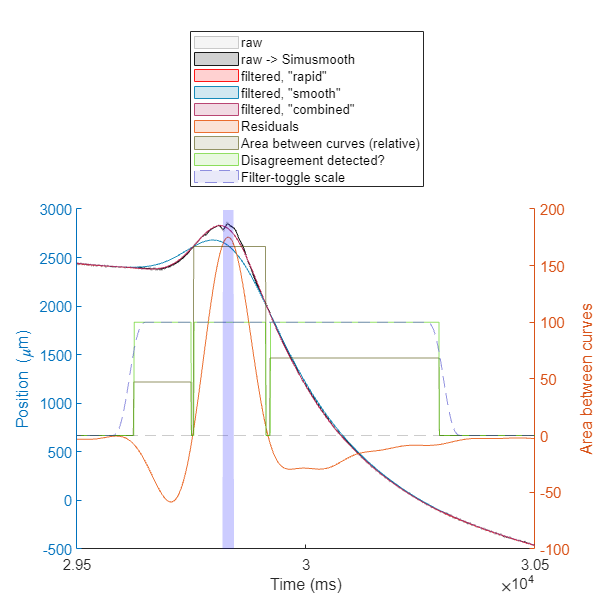

x_fil_rapid = x_processed;
x_fil_smooth = x_processed2;

% Accel. calcs
% Calculate accelerations (rapid) (in mm/s/s)
x_vel_rapid = gradient(x_fil_rapid, times_s);
x_acc_rapid = gradient(x_vel_rapid, times_s);

% Calculate accelerations (smooth) (in mm/s/s)
x_vel_smooth = gradient(x_fil_smooth, times_s);
x_acc_smooth = gradient(x_vel_smooth, times_s);


% ~~~~ CALCULATE AREA ~~~~
diffs = x_fil_rapid - x_fil_smooth;
    % % METHOD 1: Find where the difference changes sign (i.e. difference=0)
    % sign_diffs = diffs(1:end-1) .* diffs(2:end);
    % intersection_idx = find(sign_diffs <= 0);
    
    % METHOD 2: Find where the residuals are close to zero
    close_threshold_micron = 8;     % threshold for "disagreement" to be detected, in microns
    intersection_idx = find(abs(diffs*1000) <= close_threshold_micron);

% % Save wherever "intersections" are detected (for visualization)
% times_intersections = times_s(intersection_idx);
% x_intersections = diffs(intersection_idx);

% Compute areas between curves
segment_indices = arrayfun(@(i) intersection_idx(i):intersection_idx(i+1), 1:length(intersection_idx)-1, 'UniformOutput', false);
segment_areas = cellfun(@(segment) abs(trapz(times_s(segment), (x_fil_rapid(segment) - x_fil_smooth(segment)))), segment_indices);

% Convert areas to a 1D signal that can be displayed along time axis
len = length(times_s);    % Number of entries in signal
areas = zeros(size(times_ms));
for i=1:length(intersection_idx)-1
    idx_start = intersection_idx(i);
    if i~=length(intersection_idx) 
        idx_end = intersection_idx(i+1)-1; 
    else 
        idx_end = len; 
    end
    % disp("Intersection "+num2str(i)+": "+num2str(idx_start)+" to "+num2str(idx_end))
    indices = idx_start:idx_end;
    areas(indices) = segment_areas(i);
end

% Let "disagreements" be visualize-able on a 1D plot
disagreements = ones(size(times_s)); disagreements(intersection_idx) = 0;
% Only allow "disagreements" where the area-between-curves is actually
% significant
area_threshold = 10 / 10000;
disagreements(areas < area_threshold) = 0;

% Parameters for the sine wave used for smoothing
transition_time_ms = 80; % Duration of the sine wave transition in seconds
transition_samples = round(transition_time_ms); % Number of samples for the transition
strel = ones(1+2*transition_time_ms/8,1);   % 1D structuring element
disagree_dilated = imdilate(disagreements,strel);
half_sine_wave = (1-cos(linspace(0, 2*pi, transition_samples)))/2; % Sine wave, gradually rising and falling
scales = conv(disagree_dilated,half_sine_wave,'same'); scales = scales/max(scales);

% Final combination
% x_acc_smooth = gradient(gradient(x_fil_smooth, times_s),times_s);
% x_acc_rapid = gradient(gradient(x_fil_rapid, times_s),times_s);
x_final =     (1-scales).*(x_fil_smooth) + (scales).*(x_fil_rapid); 
x_afinal_v1 = (1-scales).*(x_acc_smooth) + (scales).*(x_acc_rapid); % BETTER VERSION.
x_afinal_v2 = gradient(gradient(x_final, times_s),times_s); % DO NOT USE. The `scales` bit introduces artifacts in derivatives!
        % ^ JUSTIFICATION FOR THIS "CHOICE" OF X_AFINAL:
        % We want to take the best parts of both acceleration curves.
        % However, the "scales" vector introduces discontinuities in the
        % second derivative that we do NOT want; so we instead combine the
        % acceleration curves directly (as opposed to applying "scales" to
        % the filtered position curves AND THEN taking the second
        % derivative).
        % In a similar vein, the "scales" vector's weird discontinuities in
        % 2nd derivative means that our choice of acceleration curve cannot 
        % be used to "reconstruct" the final position curve.
        % The end result is that d2x/dx2 (x_final) and x_afinal are NOT THE
        % SAME, and we kinda just have to accept that.


% ~~~~ PLOTTING ~~~~
% Left axis: positions
        % Figure window size
        figwidth_px = 700; 
        figheight_px = 700;
        close all; figure; fig=gcf; fig.Position(3:4)=[figwidth_px,figheight_px];

        % Choose xlim
        if parse_mf4_number(str_fname)==0
            xlim([1e4, 1.1e4])
        elseif parse_mf4_number(str_fname)==17
            xlim([2.95e4, 3.05e4])   % Sudden acceleration
            % xlim([3.43e4,3.53e4])    % Gradual acceleration
        end
        % Override xlim
        % xlim([1e4, 1.1e4])
        % xlim([2.95e4,3.05e4])
        % xlim([1.95e4,2.05e4]+10000)
        % xlim([1.99e4,2.01e4]+2000)
        % xlim([1.6,1.85]*10^4)
        % xlim([1.95e4,2.05e4]+2000)

yyaxis left
hold on
patchline(times_ms,x_pos_raw*1000, 'Color',[0, 0, 0, 0.2],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw');
patchline(times_ms,x_pos_simumean*1000, 'Color',[0, 0, 0, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw -> Simusmooth');
patchline(times_ms,x_fil_rapid*1000 , 'Color',[1, 0, 0, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','filtered, "rapid"');
patchline(times_ms,x_fil_smooth*1000, 'Color',[0, 0.5, 0.7, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','filtered, "smooth"');
patchline(times_ms,x_final*1000, 'Color',[0.7, 0.2, 0.4, 0.9],'LineWidth',0.1,'LineStyle','-', 'DisplayName','filtered, "combined"');
% plot(times_ms,x_fil*1000      , 'Color',[0.7, 0.0, 0.8, 0.1],'LineWidth',0.1,'LineStyle','-', 'DisplayName','raw -> Simusmooth -> SG(3,135) -> mavge(3,135) (orig)');
% scatter(times_ms, x_pos*1000.*i_newratio_nan, 40, 'rX','DisplayName','New ratio')
hold off
ylabel("Position (\mum)")
xlabel("Time (ms)")
legend('Location','best')

% Right axis: Area of residuals
yyaxis right
hold on
patchline(times_ms,diffs*1000, 'Color',[0.9, 0.3, 0., 0.8],'LineWidth',0.1,'LineStyle','-', 'DisplayName','Residuals');
patchline(times_ms,areas*10000, 'Color',[0.3, 0.3, 0, 0.6],'LineWidth',0.1,'LineStyle','-', 'DisplayName','Area between curves (relative)');
patchline(times_ms,disagreements*100, 'Color',[0.3, 0.8, 0, 0.6],'LineWidth',0.1,'LineStyle','-', 'DisplayName','Disagreement detected?');
patchline(times_ms,scales*100, 'Color',[0.3, 0.3, 0.8, 0.6],'LineWidth',0.1,'LineStyle','--', 'DisplayName','Filter-toggle scale');
% scatter(times_intersections*1000, x_intersections, 40, 'rX','DisplayName','Intersections','HandleVisibility','off')
patchline(times_ms,times_ms*0, 'Color',[0,0,0, 0.2],'LineWidth',0.5,'LineStyle','--', 'HandleVisibility','off');
hold off
ylabel("Area between curves")
% yyaxis left

        % LEGEND
        if figwidth_px >= figheight_px*1.5
            legend_position = "eastoutside";
        elseif figheight_px >= figwidth_px*0.8
            legend_position = "northoutside";
        else
            legend_position = "best";
        end
        legend("Location",legend_position);

% ylabel("Acceleration (\mum/s/s)")
% xlim([2.95e4,3.05e4])
% xlim([1.95e4,2.05e4]+2000)
% xlim([1.95e4,2.05e4]+10000)
% xlim([1.99e4,2.01e4]+2000)
% xlim([21600,22300]-000)

        % HIGHLIGHT REGIONS
        yyaxis right
        plot_highlight_regions(times_ms, mark_spikes_z, [0,0,1,0.2]);
        plot_highlight_regions(times_ms, mark_spikes_xy, [1,0,0,0.2]);
        yyaxis left

a = 5

a =      5


% 'ding'
% % Annotate the plot with area values
% for i = 1:length(x_intersections) - 1
%     mid_x = (times_intersections(i) + times_intersections(i + 1)) / 2;
%     mid_y = (x_intersections(i) + x_intersections(i + 1)) / 2;
%     text(mid_x, mid_y, sprintf('Area: %.2f', areas(i)), 'HorizontalAlignment', 'center');
% end
% 'ding'